# **EXAMEN FINAL. Torque y fuerzas del robot péndulo**

**Jesús Alejandro Gómez Bautista | A01736171**

El presente Live Script desarrolla la cinemática directa, las velocidades angulares y lineales, el modelo de energía, el langrangiano y las fuerzas y torques del robot pendulo (1 grado de libertad). 

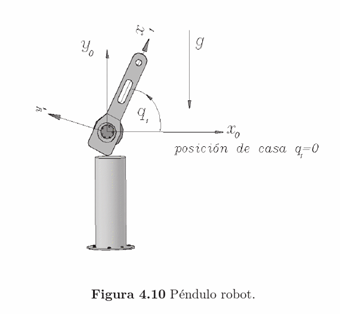

***Eje de referencia inercial***

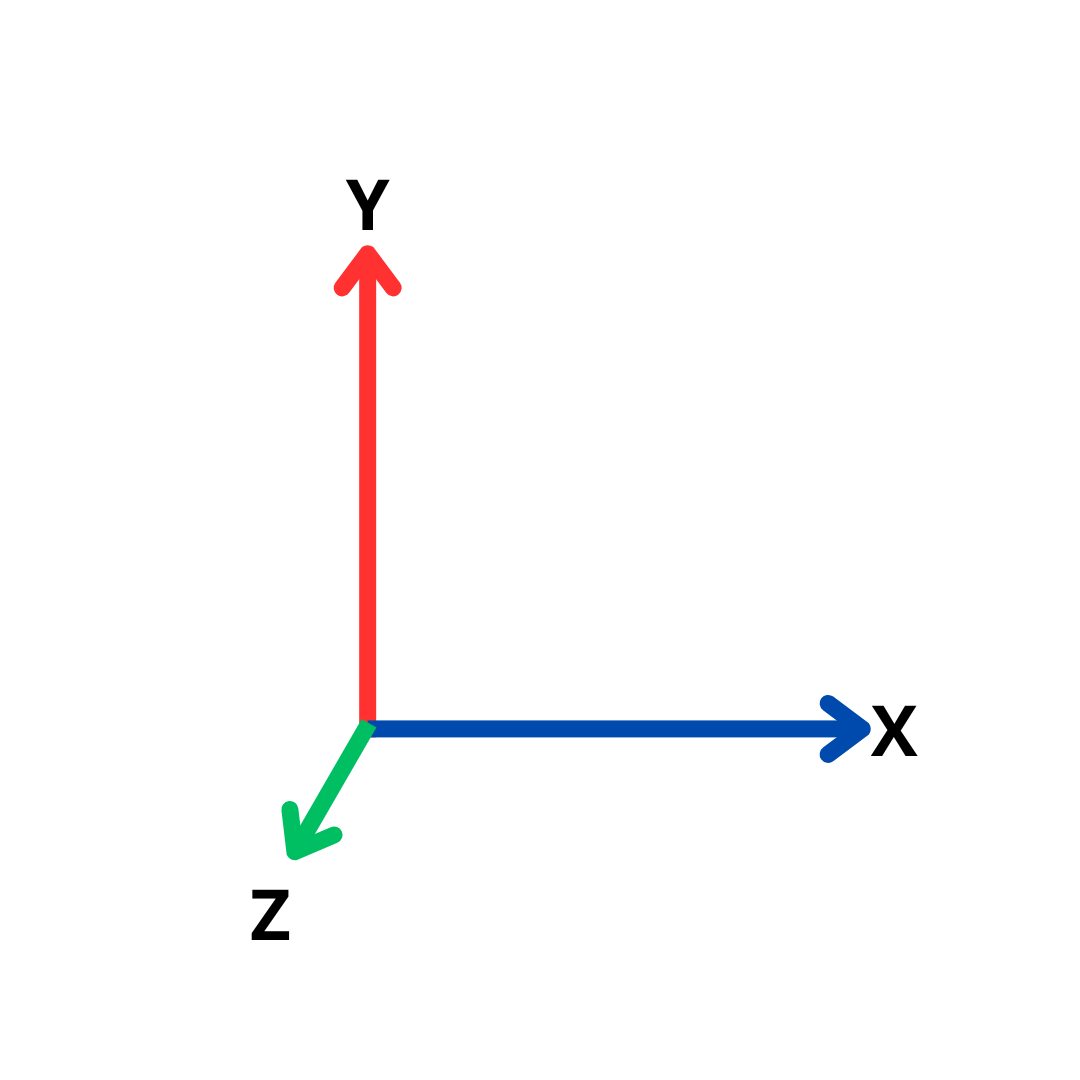

**CINEMÁTICA DIRECTA. Matrices de transformación homogénea**

%Limpieza de pantalla
clear all
close all
clc

*Exp. Código:* Estas primeras líneas nos permiten limpiar el entorno de trabajo, cerrar las figuras preexistentes (en caso de existir) y limpiar la ventana de comandos para evitar sobrescrituras o errores en caso de existir elementos compartidos con otros códigos.

%Declaración de variables simbólicas
syms th1(t)  t  %Angulos de cada articulación
syms th1p(t) %Velocidades de cada articulación
syms th1pp(t) %Aceleraciones de cada articulación
syms m1 Ixx1 Iyy1 Izz1  %Masas y matrices de Inercia
syms l1 lc1 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

*Exp. Código: *Es necesario declarar las variables necesarias para evitar errores en la compilación, dichas variables son representaciones de los elementos necearios para determinar los modelos mátematicos del robot.

 %Creamos el vector de coordenadas articulares
 Q= [th1];
 disp('Coordenadas generalizadas');

Coordenadas generalizadas


 pretty (Q);

th1(t)




 %Creamos el vector de velocidades articulares
 Qp= [th1p];
 disp('Velocidades generalizadas');

Velocidades generalizadas


 pretty (Qp);

th1p(t)




 %Creamos el vector de aceleraciones articulares
 Qpp= [th1pp];
 disp('Aceleraciones generalizadas');

Aceleraciones generalizadas


 pretty (Qpp);

th1pp(t)



Exp. Código: Estos vectores reciben las variables simbólicas para los ángulos (determinadas por el theta creado por la junta rotacional de nuestro robot de péndulo) , las velocidades (mismas que no son mas que la derivada de nuestra posición dada por el ángulo) y las aceleraciones (segunda derivada de la coordenada articular), la cantidad de elementos en estos vectores esta directamente relacionada por la cantidad de juntas existentes en el robot.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0];

%Número de grado de libertad del robot
GDL= size(RP,2)

GDL = 1

GDL_str= num2str(GDL);

*Explicación: *Nuestro modelo de robot de péndulo consta de un solo grado de libertad dado por la junta de tipo rotacional existente entre la base y el primer eslabón (y único) del robot.

%% Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1); 0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1) 0;
           sin(th1)  cos(th1) 0;
           0        0         1];

*Explicación: *Nuestro robot es de un grado de libertad con una junta rotacional, dicho esto consideramos nuestro eje de referencia a partir de la junta con una Z que emerge hacia nosostros, nuestro X es el horizonte y el componente vertical el Y, conociendo esto, la matriz de rotación es en Z debido a la orientación de nuestro marco de referencia inercial, el cual depende de nuestro theta (la apertura a la que esta junta puede llegar). 

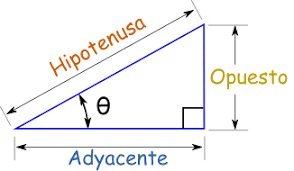

En cuanto a nuestra posición, vemos que depende no solo de nuestro theta sino también de los componentes de fuerza tanto en x como en y, considerando la figura arriba, tenemos que nuestro componente en x es igual a el coseno, mientras que el y es el seno. Este valor esta influenciado a su vez por la longitud del slabón. Un valor más largo proporciona una mayor velocidad angular para una misma velocidad lineal.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);

end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



*Explicación: *La matriz de transformación local interpreta la relación entre el sistema de coordenadas del eslabón y el sistema de coordenadas adyacentes, toma en cuenta la longitud del eslabón, la rotación y traslación del entre los sistemas, mientras que la transformación global describe la relación entre el sistema de coordenadas del eslabon con respecto al sistemas de coordenadas base, esta toma en cuenta todas las transformaciones a lo largo de la cadena cinemática. En este caso, al existir simplemente una traslación a lo largo de un eje, la matriz de transformación local es igual a la global.

**JACOBIANOS. Obtención de velocidad lineal y angular**

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    


%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify(Jv_a);
Jw_a= simplify(Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
\        0        /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0 \
|   |
| 0 |
|   |
\ 1 /




%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
pretty(Jacobiano);

/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
|        0        |
|                 |
|        0        |
|                 |
|        0        |
|                 |
\        1        /




%Obtenemos vectores de Velocidades Lineales y Angulares
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp);
pretty(V);

/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp);
pretty(W);

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



*Explicación velocidades lineal: *el primer elemento representa la velocidad lineal en dirección de x mientras que el segundo representa la velocidad lineal en la dirección de y. El tercer elemento es cero pues no presenta movimiento lineal en dirección de z. La matriz describe la relación de las coordenadas del extremo del péndulo con respecto a las vlocidades generalizadas, la presencia de seno y coseno indican que las velocidades lineales dependen de la posición angular dada por theta, así mismo, la longitud del eslabón también influye en la magnitud de la velocidad lineal, la relación con las velocidades generalizadas esta dada por la cinemática del robot.

*Explicación velocidades angulares: *el primer y segundo termino son igual a 0 pues aunque se mueve en xy no posee componentes de velocidad en x o en y. El tercer elemento dado por th1p (velocidad) existe y corresponde a la rotación del pendulo en el eje z, lo cual hace que la velocidad angular dependa de esta rotación.

**ENERGÍA CINÉTICA.**

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

La matriz de inercia es necesaria para el analisis de la dinámica rotacional en el eslabón 1 lo cual nos relaciona directamente con la cinéticaa y la cinemática del robot.

La forma en que esta está construida, similar a una matriz de identidad, nos indica que la masa del eslabón 1 está distribuida de manera uniforme alrededor de los ejes principales. Cada elemento en ella representa la resistencia de rotación en cada uno de los ejes.

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);


Apartir del cálculo de velocidades angulares y lineales de manera analítica, extraemos de cada uno de los vectores los elementos de la velocidad lineal y angular para cada uno de los elementos. Para la angular, cada uno recibe ese nombre en lugar de x,y o z pues son sus equivalentes en cuanto al giro que se debe hacer en esos ejes.

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL)=PO(:,:,GDL);
Jw_a1(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
pretty(Jacobiano);

/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
|        0        |
|                 |
|        0        |
|                 |
|        0        |
|                 |
\        1        /




%Obtenemos vectores de Velocidades Lineales y Angulares
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
pretty(V1);

/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1));
pretty(W1);

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /




%Calculamos la energía cinética para cada uno de los eslabones

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1




K_Total= simplify (K1);
%pretty (K_Total);

*Ecplicación Matriz Jacobiana: *Antes de pasar con la explicación de la Energía Cinética presente en el eslabón 1, veo necesario explicar lo que es una matriz Jacobiana, esta nos permite relacionar las velocidades generalizadas con las del extremo del robot, la cual nos permite calcular las velocidades en los extremos a partir de las velocidades articulares.

Explicación Energía cinética: Esta expresión muestra la contirbución de la inercia, la masa y la geometría del eslabón en su energía cinética, tenemos que:

- Izz1 representa la inercia existente en el eslabón alrededor de z, lo que coincide con el eje de rotación al cual orientamos nuestra junta rotacional. Relaciona la distribución de la masa y la resistencia existente en la rotación en z.

- En el segundo termino, la suma de los terminos l1 y lc1 no es más que la representación de la distancia total desde el punto de rotación hasta el centro de masa.

- El término (cos(th1(t) - th1(t)) esta relacionado con la orientación angular del eslabón, mientras que th1 es el ángulo de rotación del eslabón 1.

**ENERGÍA POTENCIAL**


%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(3); %Tomo la altura paralela al eje z

 U1=m1*g*h1;


La altura paralela al eje z considera la altura vertical desde la posición más baja hasta el punto donde el péndulo se úbica.


 %Calculamos la energía potencial total
 U_Total= U1;

 %Obtenemos el Lagrangiano
 disp('Lagrangiano');

Lagrangiano


 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1



El primer término del langrangiano (Izz1 `th1p(t)`|^2) nos dice la relación que existe entre la energía cinética rotacional del eslabón 1 alrededor del eje z. En el segundo término, la expresión m1(l1 + lc1) representa la energía cinética traslacional en el eslabón 1.

Entendamos al langrangiano como la forma de describir la dependencia a las coordenadas generalizadas y sus velocidades. El hecho de que exista cos(th1) en el termino, indica que la energía cinética rotacional depende de la orientación del eslabón.

El langrangiano es fundamental par poder derivar las ecuaciones de movimiento. Proporciona información sobre la dinámica del eslabón 1 y como sus varables afectan a la energía cinética total.

%Modelo de Energía
disp('Modelo de Energía');

Modelo de Energía


 H= simplify (K_Total+U_Total);
 pretty (H)

              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1



Algo curioso que puede observarse durante la generación del langrangiano y el modelo de energía es la similitud de estos en el modelo del robot de péndulo, se denota al langrangiano como la diferencia entre la energía cinética y la energía potencial, mientas que la energía total del sistema se expresa como la suma de la energía cinética y la energía potencial.

**ECUACIONES DE MOVIMIENTO**

 %Lagrangiano derivado con respecto a la primera coordenada generalizada de
 %velocidad

 %Definimos un vector columna de derivadas con respecto al tiempo
 %En este vector agrego las velocidades y aceleraciones
  %Derivadas respecto al tiempo
 Qd=[th1p(t); th1pp(t)];


Al ser de un grado de libertad, solo contamos con las velocidades y aceleraciones del ángulo.


 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

 %Definimos el torque 1
 disp('Torque');

Torque


 t1= dQ1*Qd- diff(Lagrangiano, th1)

$$t1(t) = \begin{array}{l} \mathrm{th1pp}\left(t\right)\,\left({\mathrm{Izz}}_{1}\,{\mathrm{sign}\left(\mathrm{th1p}\left(t\right)\right)}^{2}+2\,{\mathrm{Izz}}_{1}\,\left|\mathrm{th1p}\left(t\right)\right|\,\delta (\mathrm{th1p}\left(t\right))+\frac{\sigma_{2}\,{\mathrm{sign}\left(\mathrm{th1p}\left(t\right)\right)}^{2}\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}}+\frac{2\,\left|\mathrm{th1p}\left(t\right)\right|\,\delta (\mathrm{th1p}\left(t\right))\,\sigma_{2}\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\\ \sigma_{2}=\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right) \end{array}$$

El torque 1 (es decir, del primer eslabón) se obtiene a partir de las derivadas de la velocidad en la primera coordenada generalizada.

Se utiliza la derivada parcial de las derivadas de la energía cinética y potencial con respecto a th1.


%Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia

%Extraemos coeficientes de aceleraciones

M=[diff(t1, th1pp)];
rank (M);
disp('Coeficientes de aceleración');

Coeficientes de aceleración


M=M(t)

$$M = \begin{array}{l} {\mathrm{Izz}}_{1}\,{\mathrm{sign}\left(\mathrm{th1p}\left(t\right)\right)}^{2}+2\,{\mathrm{Izz}}_{1}\,\left|\mathrm{th1p}\left(t\right)\right|\,\delta (\mathrm{th1p}\left(t\right))+\frac{\sigma_{2}\,{\mathrm{sign}\left(\mathrm{th1p}\left(t\right)\right)}^{2}\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}}+\frac{2\,\left|\mathrm{th1p}\left(t\right)\right|\,\delta (\mathrm{th1p}\left(t\right))\,\sigma_{2}\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\\ \sigma_{2}=\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right) \end{array}$$

La matriz de inercia contiene los coeficientes de aceleración, se deriva parcialmente en el tiempo con respecto a todas las variables. 

 %Fuerzas Centrípetas y de Coriolis
 
 %Definimos Mp

M11=[diff(M(1,1),th1)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 


Mp=[M11];

El cálculo de la matriz de fuerzas centrípedas y de Coriolis se entiende como las derivadas de la energí cinética y la energía potencial.

%Definimos la energía cinética en su forma matricial
disp('Energía cinética en su forma matricial');

Energía cinética en su forma matricial


k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1)];

%Fuerzas centrípetas y de Coriolis
disp('Fuerza Centrípetas y de Coriolis');

Fuerza Centrípetas y de Coriolis


 C= Mp*Qp-dk

$$C(t) = 0$$

La fuerza centripeda es necesaria para mantener al objeto en movimiento en una trayectoria circular en lugar de moverse en línea recta. El efecto coriolis se determina por la masa y la velocidad de rotación del objeto.


 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th1pp,r);

 %Torque gravitacional en el motor 1
 G1=a2;

Se sustituyen las velocidades y aceleraciones por cero para obtener el torque gravitacional en el motor 1.

% Vector de par gravitacional
disp('Vector de par gravitacional');

Vector de par gravitacional


G=[G1]

$$G(t) = \begin{array}{l} \mathrm{cero}\,\left({\mathrm{Izz}}_{1}\,{\mathrm{sign}\left(\mathrm{cero}\right)}^{2}+2\,{\mathrm{Izz}}_{1}\,\left|\mathrm{cero}\right|\,\delta (\mathrm{cero})+\frac{\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\,\bar{m_{1}}\,{\mathrm{sign}\left(\mathrm{cero}\right)}^{2}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}}+\frac{2\,\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\,\left|\mathrm{cero}\right|\,\delta (\mathrm{cero})\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2} \end{array}$$